# System of Three Equations

## Task 1

Systems with three equations and three unknowns are more challenging to visualize, but the process for solving them with `fsolve` is the same.

In this activity, you'll visualize and solve the following system of equations.

x2+y2+z2−3=03x−2y+z−2=0sin(x)cos(y)+z=0

Task

Create a function handle to an anonymous function for each equation: 

-  create `mySph` for the implicit function x2+y2+z2−3, 

-  create `myPlane` for the implicit function 3x−2y+z−2, and 

-  create `myFun` for the implicit function sin(x)cos(y)+z. 

Each function should accept three inputs: `x`, `y`, and `z`. Remember to use element-wise operators in your function definitions.

mySph=@(x,y,z) x.^2+y.^2+z.^2-3

mySph = function_handle with value:
    @(x,y,z)x.^2+y.^2+z.^2-3


myPlane=@(x,y,z) 3.*x-2.*y+z-2

myPlane = function_handle with value:
    @(x,y,z)3.*x-2.*y+z-2


myFun=@(x,y,z) sin(x).*cos(y)+z

myFun = function_handle with value:
    @(x,y,z)sin(x).*cos(y)+z


## Task 2

The `fimplicit3` function creates an implicit surface plot defined by f(x,y,z)=0.

`fimplicit3``(``f``)`

Similar to `plot`, you can specify the color of the surface with an additional input.

`fimplicit3``(``f``,``"r"``)`

You can make the surface transparent by setting the `"FaceAlpha"` property to a value between 0 and 1.

`fimplicit3``(``f``,``"r"``,``"FaceAlpha"``,``0.3``)`

Task

Plot `mySph`, `myPlane`, and `myFun` together as implicit surface plots. 

Set the surface color of `mySph` to yellow, `myPlane` to red, and `myFun` to blue. Set `"FaceAlpha"` to `0.4` for all three plots.

You may want to label the x, y, and z axes. 

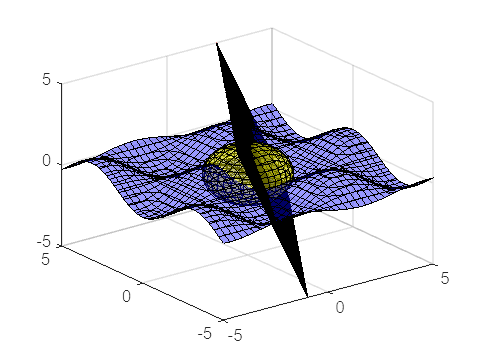

fimplicit3(mySph,"y","FaceAlpha",0.4)
hold on
fimplicit3(myPlane,"r","FaceAlpha",0.4)
fimplicit3(myFun,"b","FaceAlpha",0.4)
hold off

## Task 3

When you create a function handle `f` for a system with three equations and three variables, the vector input `w` is a 3 element vector made up of the variables x, y, and z. The definition of `f` returns a 3 element vector, with each element representing the corresponding equation in the system.

`f` `=` `@``(``w``)` `[` `f1``(``w``(``1``)``,``w``(``2``)``,``w``(``3``))``;`

           `f2``(``w``(``1``)``,``w``(``2``)``,``w``(``3``))``;`

           `f3``(``w``(``1``)``,``w``(``2``)``,``w``(``3``))` `]`

Task

Create a function handle `mySystem` to an anonymous function for the system of equations. 

Keep the equations in the order given, i.e., `mySph` is the first equation, `myPlane` is the second, and `myFun` is the third.

mySystem=@(w)[mySph(w(1),w(2),w(3));
    myPlane(w(1),w(2),w(3));
    myFun(w(1),w(2),w(3))]

mySystem = function_handle with value:
    @(w)[mySph(w(1),w(2),w(3));myPlane(w(1),w(2),w(3));myFun(w(1),w(2),w(3))]


## Task 4

All three surfaces intersect at two points, so the system has two solutions.

Find the solution of the system near the point (−0.5,−1.5,−0.5). Assign the result to `wRoot`.

w0=[-0.5 -1.5 -0.5]

w0 =    -0.5000   -1.5000   -0.5000


wRoot=fsolve(mySystem,w0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


wRoot =    -0.4358   -1.6758   -0.0442


## Further Practice

You can add `wRoot` to your plot using the `plot3` function.

`hold` `on`

`plot3``(``wRoot``(``1``)``,``wRoot``(``2``)``,``wRoot``(``3``)``,``...     `

       `"m."``,``"MarkerSize"``,``40``)`

`hold` `off`

Try rotating your plot to approximate the location of the second intersection point. Then find it using `fsolve`, and add it to your plot.

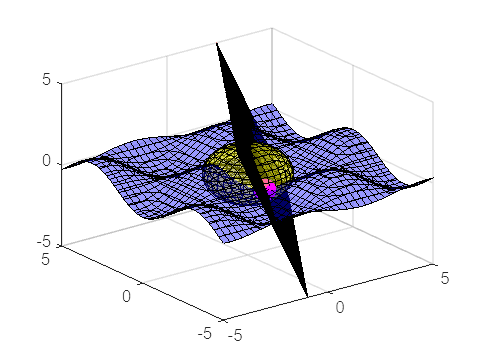

hold on
plot3(wRoot(1),wRoot(2),wRoot(3),"m.","MarkerSize",40)
hold off